## Import Menzies Data

data = readtable("data.xlsx");

data.impwh = erase(data.impwh,',');
data.epoch_timestamp = erase(data.epoch_timestamp, ',');

data.impwh = str2double(data.impwh);
data.impwh = data.impwh./1000;
%data.impwh is a running total. The total starts at like 10 million kWh, 
% Should I minus the first value from all of them to get just the
%running total of the year I have data for? Or is that messing with data
%and shit. 
data.epoch_timestamp = str2double(data.epoch_timestamp)

data = 8760×25 table
    meter_serial            meter_desc                   tstamp              date            day           time          tou         week_number      impwh       difference_imp_kwh     ptot      stot     expwh    difference_exp_kwh    pftot      md       qtot     epoch_timestamp       interval_start       waste    meter_id    tou_id    season_profile_id    season_class_id    tariff_id
    ____________    __________________________    ____________________    ___________    _

%Still need to sort out
%        days of the week
%        null entries
%        Tariff_id entry


### Dimensionality Reduction

%Try PCA

%Try Sequential Feature Selection




### Anomaly Detection

%Can use statistical methods to find outliers

%Can try use some ML ting



#### Fucken around and trying some shit

[https://www.mathworks.com/help/deeplearning/ug/time-series-forecasting-using-deep-learning.html](https://www.mathworks.com/help/deeplearning/ug/time-series-forecasting-using-deep-learning.html) Useful shit for 

predicting future timeseries values.

%removing casue fitrsvm doesn't like them
data  = removevars(data,["tstamp","date","interval_start"]);

numObs = height(data);
percentSplit = 0.8;
idxTrain = 1:floor(percentSplit*numObs);                                
idxTest = floor(percentSplit*numObs)+1:numObs; 
dataTrain = data(idxTrain,:);
dataTest = data(idxTest,:);   

mdl = fitrsvm(dataTrain,"ptot","Standardize",true, "KernelFunction","polynomial");

mdlLoss = loss(mdl, dataTest)

mdlLoss = 55.5787

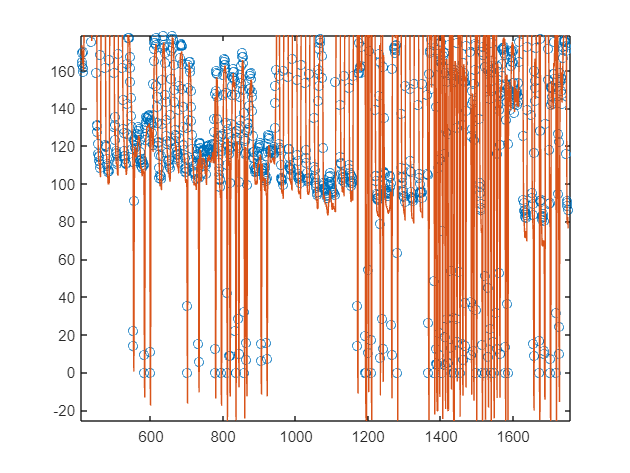

ptotPred = predict(mdl, dataTest);

plot(dataTest.ptot, "o")
hold on
plot(ptotPred)
hold off

%evaluateFit(dataTest.ptot, ptotPred, "SVM")


% numChannels = size(data(:,:),1)
% 
% figure
% tiledlayout(13,2)
% for i = 1:25
%     nexttile
%     stackedplot(data(1:100,i))
% 
%     xlabel("Time Step")
% end